# GMM

clear;clc;
X_train = load('CSE575-HW03-Data.csv');

gauss = @(x,mu,sigma) (1/((2*pi)^size(x,1)*det(sigma))^0.5)*exp(-0.5*(x-mu)'*(sigma\(x-mu)));

## Data Preparation

D = size(X_train,2);
K = 2;
% mu sigma are the initial means and variance for GMM, assigned using the K means returned by K-means clustering implemented in Problem 2
load('mu_init_gmm.mat')
load('sigma_init_gmm.mat')
load('pi_k_init_gmm.mat')
% Posterior probability
gznk = gamma_znk(X_train,pi_k,mu,sigma,gauss);
N_k = sum(gznk,1)';

## EM Algorithm

% Initialize the log liklihood
LL = log_liklihood(X_train,pi_k,mu,sigma,gauss);
prev_LL = 0;
% Loop until change in log loklihood is less then threshold
while(abs(prev_LL-LL) > 1e-5)
    prev_LL = LL;
    for k=1:K
        % Update means
        temp_m = 0;        
        for i=1:size(X_train,1)
            temp_m = temp_m + gznk(i,k) * X_train(i,:);
        end
        mu(k,:) = temp_m/N_k(k);

        % Update variance
        temp_s = 0;
        for i=1:size(X_train,1)
            temp_s = temp_s + gznk(i,k) * (X_train(i,:)-mu(k,:))'*(X_train(i,:)-mu(k,:));
        end
        sigma(k,:,:) = temp_s/N_k(k);
    end

    % Compute posterior
    gznk = gamma_znk(X_train,pi_k,mu,sigma,gauss);
    N_k = sum(gznk,1)';

    % Reassign mixing coefficients
    pi_k = N_k/sum(N_k);

    % Recompute log liklihood
    LL = log_liklihood(X_train,pi_k,mu,sigma,gauss);    
%     disp(LL);
end

## Plot

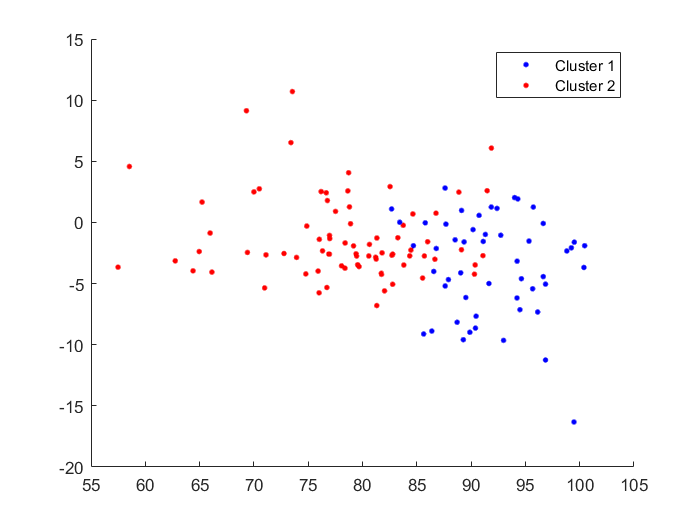

figure;
hold on;
for j=1:size(X_train,1)
    if gznk(j,1)<gznk(j,2)
        plot(X_train(j,1),X_train(j,2),'.','Color','red','MarkerSize',10)
    else
        plot(X_train(j,1),X_train(j,2),'.','Color','blue','MarkerSize',10)
    end
end
legend('Cluster 1', 'Cluster 2')
hold off;

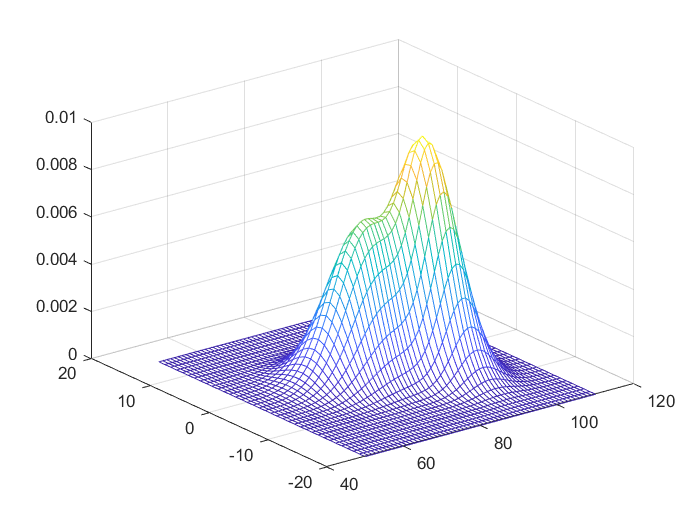

[x,y] = meshgrid(50:1:110,-20:1:15);
z = zeros(size(x));
mu_ = mu(:,1:2);
sigma_ = sigma(:,1:2,1:2);
for i=1:size(z,1)
    for j=1:size(z,2)
        q = [x(i,j);y(i,j)];
        z(i,j) = gauss(q,mu_(1,:)',squeeze(sigma_(1,:,:))) + gauss(q,mu_(2,:)',squeeze(sigma_(2,:,:)));
    end
end
figure;
mesh(x,y,z);

function value = gamma_znk(X_train,pi_k,mu,sigma,fun)
    value = zeros(size(X_train,1),size(pi_k,1));
    for i=1:size(X_train,1)
        temp = 0;
        for k=1:size(pi_k,1)
            value(i,k) = pi_k(k) * fun(X_train(i,:)',mu(k,:)',squeeze(sigma(k,:,:)));
            temp = temp + value(i,k);
        end
        value(i,:) = value(i,:) / temp;
    end
end

function value = log_liklihood(X_train,pi_k,mu,sigma,fun)
    value = 0;
    for i=1:size(X_train,1)
        temp = 0;
        for k=1:size(pi_k,1)
            temp = temp + pi_k(k) * fun(X_train(i,:)',mu(k,:)',squeeze(sigma(k,:,:)));
        end
        value = value + log(temp);
    end
    value = -value;
end